clear all,clc

a = input('Enter the first digit of one of the students id number : ','s');
b = input('Enter the last digit of one of the students id number : ','s');

a = str2double(a); 
b = str2double(b);

if isreal(a) && isreal(b)
    syms x;
    fx = x^3 + 3*x^2 + a*x + b;
    roots = roots(sym2poly(fx));
    real_roots = [];

    for i = 1:length(roots)
        if isreal(roots(i))
            real_roots(i) = roots(i);
        end
    end

    disp('Real roots of the equation:');
    disp(real_roots);

else
    disp('Error - a and b must be real numbers');
    return
end

Real roots of the equation:


   -2.0000



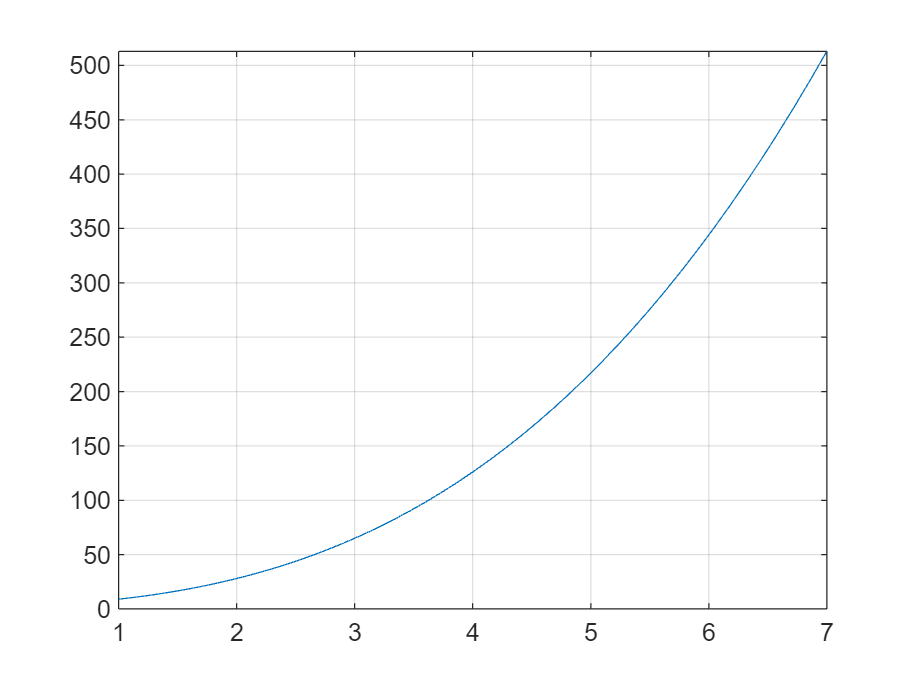


idNumber = input("Enter one of the students id number : ");
idString = num2str(idNumber);
digits = double(idString) - double('0');
c = min(digits);
d = max(digits);


n = 10000;
dx = (d-c)/n;
x = [c:dx:d];
fx = x.^3 + 3*x.^2 + a*x + b;
I = double(abs(sum(fx*dx)));
fplot(@(x) x.^3 + 3*x.^2 + a*x + b, [c, d]);
grid on;



approximate_integral = I;
syms x;
exact_integral = double(int(x^3 + 3*x^2 + a*x + b, c, d));
approximation_error = double(abs(exact_integral - approximate_integral));


disp('Approximate Integral Value : ');

Approximate Integral Value : 


disp(approximate_integral);

   1.0262e+03



disp('Approximation Error : ');

Approximation Error : 


disp(approximation_error);

    0.1566





syms x;
f = @(x) x.^3 + 3*x.^2 + a*x + b;
[x_min, f_min] = fminbnd(f, c, d);
[x_max, f_max] = fminbnd(@(x) -f(x), c, d);

disp('Absolute minimum point:');

Absolute minimum point:


disp(['(', num2str(abs(x_min)), ' , ', num2str(abs(f_min)),')']);

(1.0001 , 9.0007)


disp('Absolute maximum point:');

Absolute maximum point:


disp(['(', num2str(abs(x_max)), ' , ', num2str(abs(f_max)),')']);

(6.9999 , 512.9889)
